a)

n_dardos=20;
n_alvos=100;

alvos_atingidos=randi(n_alvos,n_dardos,10000);
matriz=zeros(1,10000);
for l = 1:10000
    [x,y]=size(unique(alvos_atingidos(:,l)));
    matriz(l)=x==n_dardos;
end

probabilidade_nenhum_alvo_atingido_mais_do_que_uma_vez=sum(matriz)/10000

probabilidade_nenhum_alvo_atingido_mais_do_que_uma_vez = 0.1288

b)

n_dardos=20;
n_alvos=100;

alvos_atingidos=randi(n_alvos,n_dardos,10000);

for l = 1:10000
    [x,y]=size(unique(alvos_atingidos(:,l)));
    matriz(l)=x<=n_dardos-1;
end

probabilidade_pelo_menos_1_alvo_atingido_2_ou_mais_vezes=sum(matriz)/10000

probabilidade_pelo_menos_1_alvo_atingido_2_ou_mais_vezes = 0.8682

c)

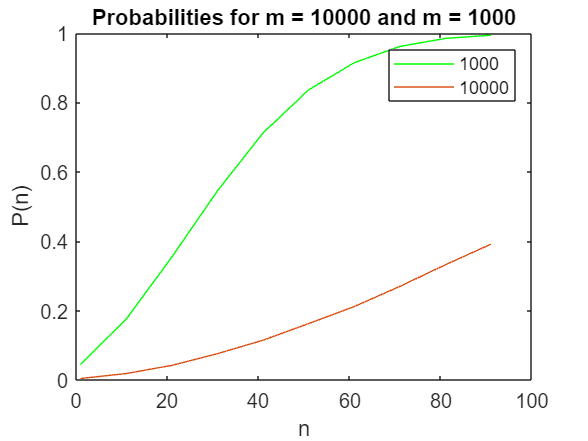

m = 1000;
N = 1e5;
nValues = 1:10;     
prob = zeros(1,10);

for n = 1 : 10
    a = randi(m, n*10, N);
    
    for i = 1:N
        res(i) = length(unique(a(:, i))) < n*10;
    end
    prob(n) = sum(res)/N;
end


subplot(1,1,1)
plot(1:10:100, prob,"g")
hold on


m = 10000;
N = 1e5;
prob = zeros(1,10);

for n = 1 : 10
    a = randi(m, n*10, N);
    
    for i = 1:N
        res(i) = length(unique(a(:, i))) < n*10;
    end
    prob(n) = sum(res)/N;
end

subplot(1,1,1)
plot(1:10:100, prob)

xlabel('n')
ylabel('P(n)')
title('Probabilities for m = 10000 and m = 1000')


legend("1000", "10000")

d)

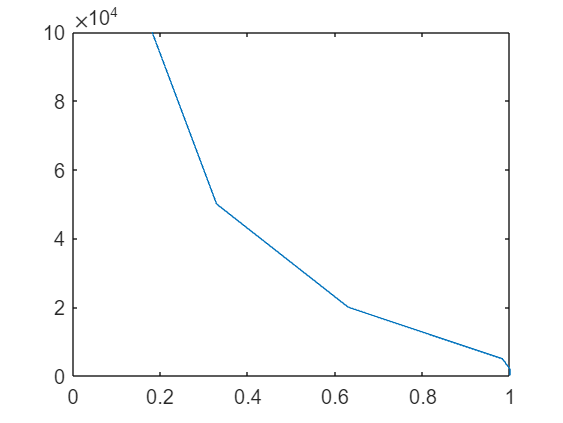

n = 200;
m = [200 500 1000 2000 5000 10000 20000 50000 100000];
N = 1e5;

for i = 1 : 9
    a = randi(m(i), n, N);
    
    for j = 1:N
        res(j) = length(unique(a(:, j))) < n;
    end
    prob2(i) = sum(res)/N;
end

plot(prob2, m)